# Get Started with Transfer Learning

This example shows how to use transfer learning to retrain ResNet-18, a pretrained convolutional neural network, to classify a new set of images. Try this example to see how simple it is to get started with deep learning in MATLAB®.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network with randomly initialized weights from scratch. You can quickly transfer learned features to a new task using a smaller number of training images.

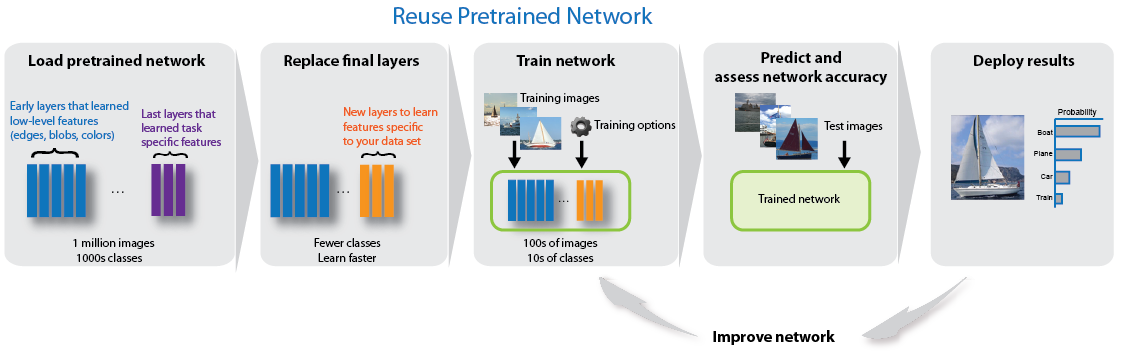

## Load Data

Unzip and load the new images as an image datastore. Divide the data into training and validation data sets. Use 70% of the images for training and 30% for validation.

imageFolder = "labeled_pieces_cropped";
augmenter = imageDataAugmenter("RandXTranslation", [-10 10], "RandYTranslation", [-10 10], "RandRotation", [-5 5]);
datastore = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
tbl = countEachLabel(datastore)

tbl = 7×2 table
    Label     Count
    ______    _____

    bishop     457 
    empty      726 
    king       332 
    knight     453 
    pawn       873 
    queen      332 
    rook       456 


% Determine the smallest amount of images in a category
minSetCount = min(tbl{:,2}); 

% Limit the number of images to reduce the time it takes
% run this example.
%maxNumImages = 100;
%minSetCount = min(maxNumImages,minSetCount);

% Use splitEachLabel method to trim the set.
datastore = splitEachLabel(datastore, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(datastore)

ans = 7×2 table
    Label     Count
    ______    _____

    bishop     332 
    empty      332 
    king       332 
    knight     332 
    pawn       332 
    queen      332 
    rook       332 



[imdsTrain,imdsValidation] = splitEachLabel(datastore,0.7,'randomized');

## Load Pretrained Network

Load the pretrained ResNet-18 network. If Deep Learning Toolbox™ Model *for ResNet-18 Network* is not installed, then the software provides a download link. ResNet-18 has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a label for the object in the image together with the probabilities for each of the object categories. To perform transfer learning using different pretrained networks, see [Train Deep Learning Network to Classify New Images](docid:nnet_examples.mw_50469739-1a06-4865-b1b2-e9c149b86f96).

net = resnet50;
analyzeNetwork(net)

## Replace Final Layers

To retrain ResNet-18 to classify new images, replace the last fully connected layer and the final classification layer of the network. In ResNet-18, these layers have the names `'fc1000'` and  `'ClassificationLayer_predictions'`, respectively. Set the new fully connected layer to have the same size as the number of classes in the new data set (5, in this example). To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer.

numClasses = numel(categories(imdsTrain.Labels));
if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1x2 Layer array with layers:

     1   'fc1000'                       Fully Connected         1000 fully connected layer
     2   'ClassificationLayer_fc1000'   Classification Output   crossentropyex with 'tench' and 999 other classes

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:174) = freezeWeights(layers(1:174));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastore have different sizes. Use an augmented image datastore to automatically resize the training images. You can also use an `imageDataAugmenter` to specify additional augmentation operations to perform on the training images to help prevent the network from overfitting.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, "DataAugmentation", augmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation, "DataAugmentation", augmenter);

Specify the training options, including mini-batch size and validation data. Set `InitialLearnRate` to a small value to slow down learning in the transferred layers. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and slower learning in the other layers.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',64, ...
    'MaxEpochs',40, ...
    'InitialLearnRate',0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 2, ...
    'LearnRateDropFactor', 0.8, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. 

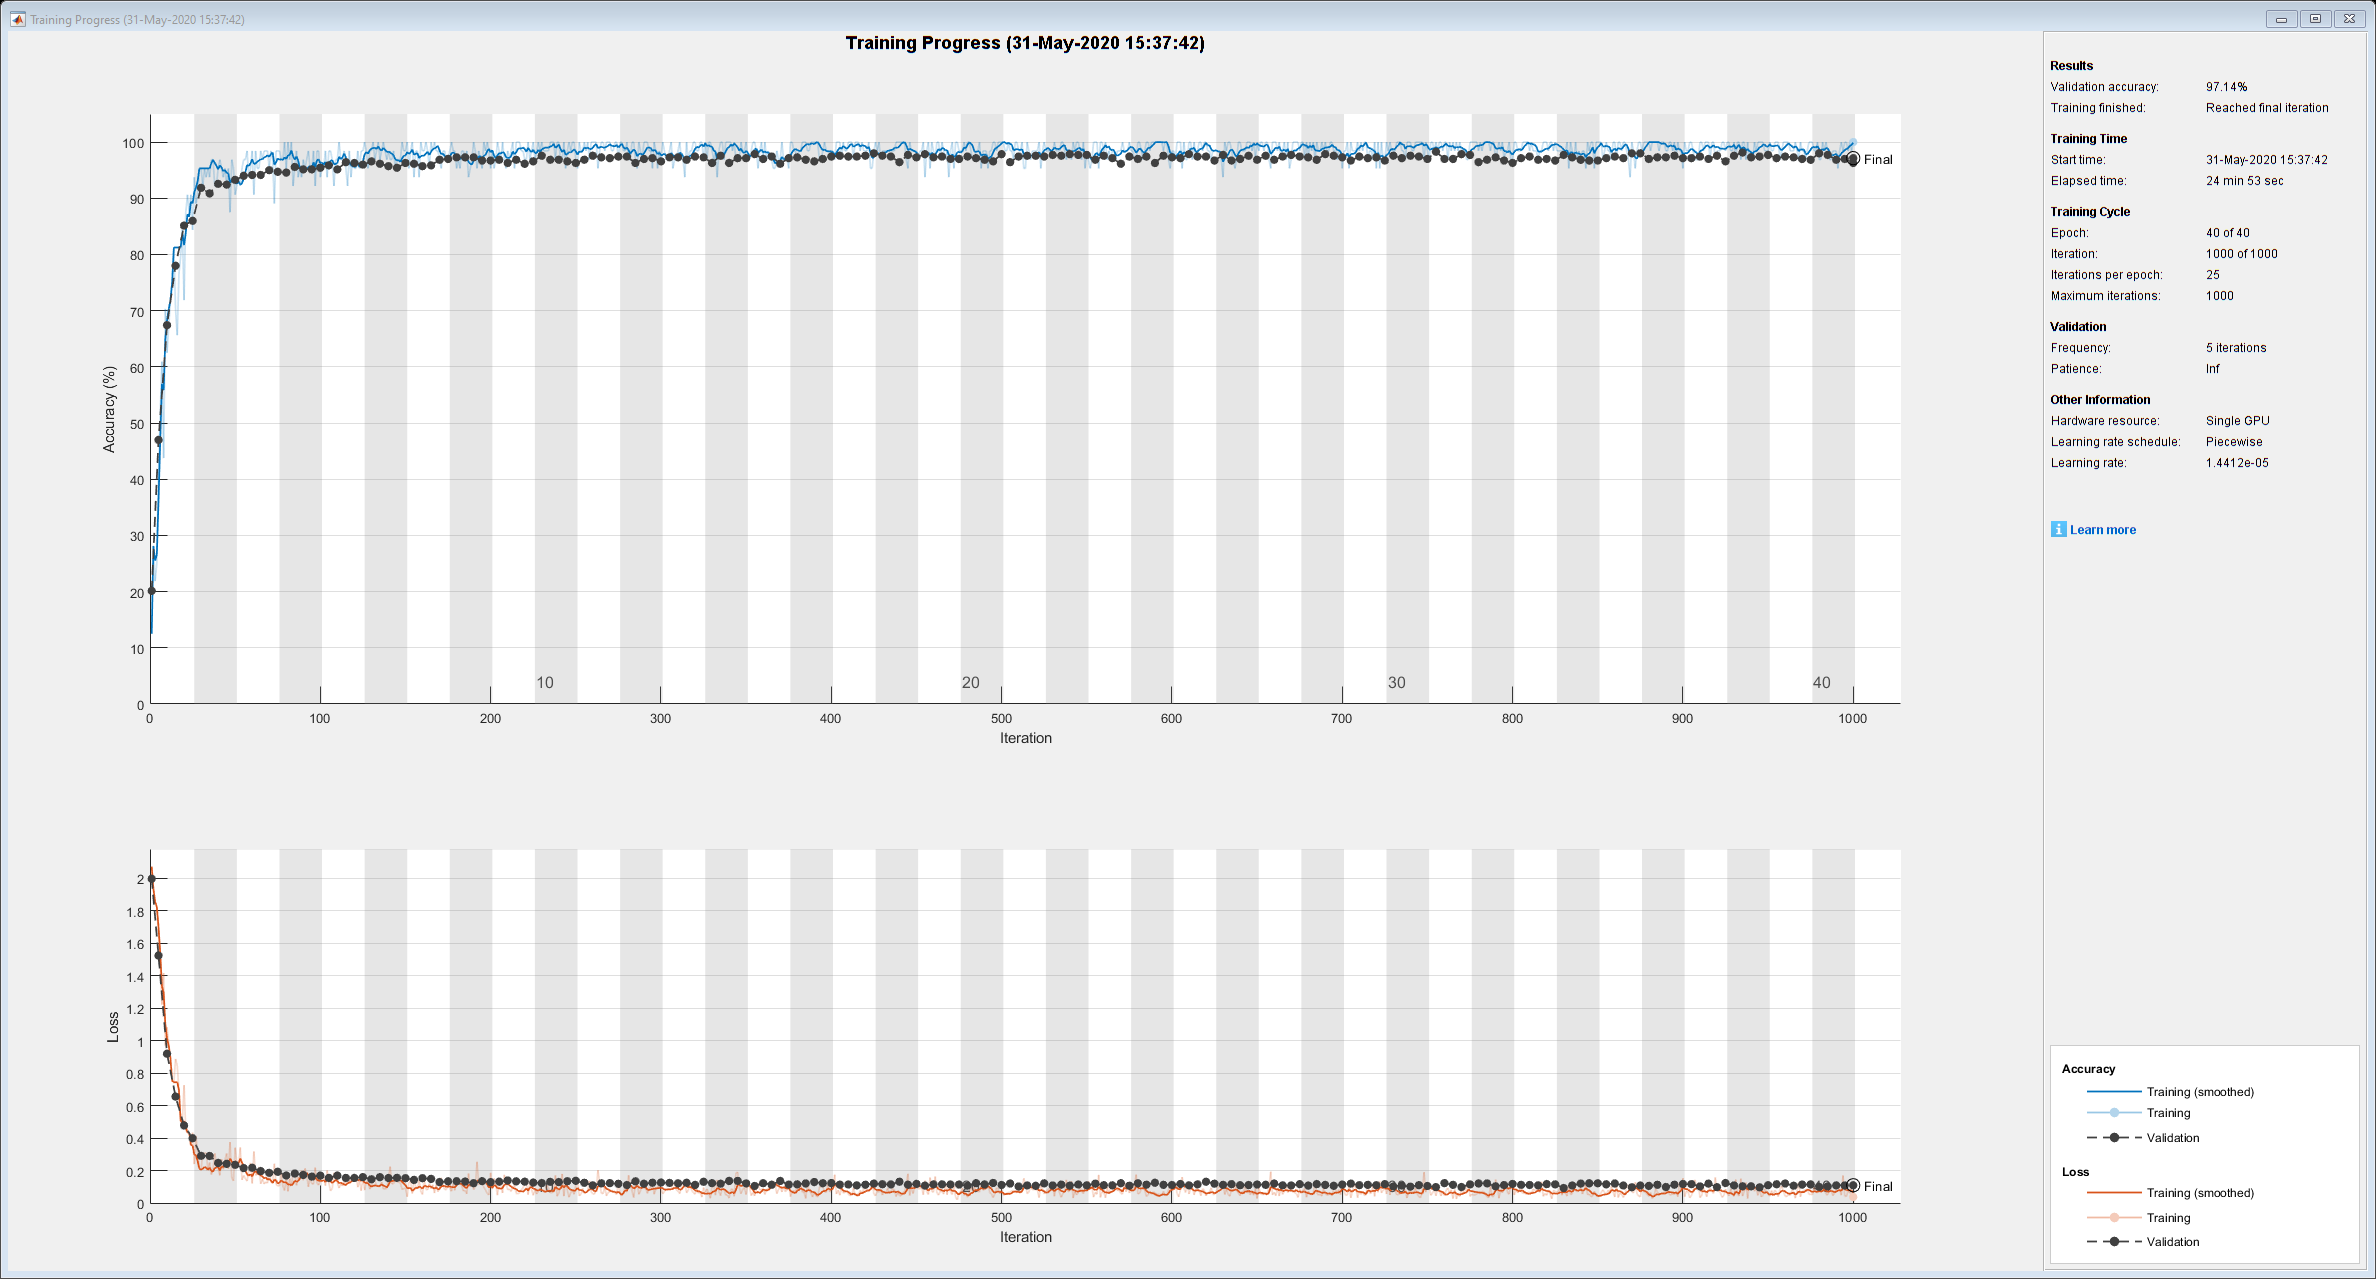

trainedNet = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

YPred = classify(trainedNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9786

## Learn More

To perform transfer learning using different pretrained networks, see [Train Deep Learning Network to Classify New Images](docid:nnet_examples.mw_50469739-1a06-4865-b1b2-e9c149b86f96). To try transfer learning using the Deep Network Designer app, see [Transfer Learning with Deep Network Designer](docid:nnet_ug.mw_8cf1cec2-ffcb-4556-99e8-eac5006a1cd1). For a list and comparison of the pretrained networks, see [Pretrained Deep Neural Networks](docid:nnet_ug.bvf9ych-1). 

*Copyright 2018 The MathWorks, Inc.*